# Euler Bernoulli beam with cubic spring and damper

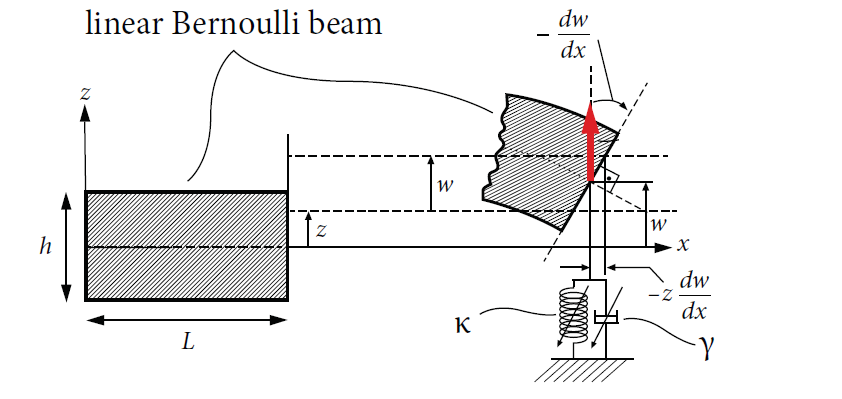

Instead of external excitation on the last node, the excitation here is of parametric type. The tip of the beam is subject to linear parametric excitation. The experiment this example is based on can be found in 

Chen, C. C. & Yeh, M. K.:  *Parametric instability of a beam under electromagnetic excitation*. Journal of Sound and Vibration 240,747–764, [https://doi.org/10.1006/jsvi.2000.3255](https://doi.org/10.1006/jsvi.2000.3255) 

## Generate model

clear all
nElements = 5;
kappa = 50; % cubic spring
gamma = 0.01; % cubic damping
[M,C,K,fnl,fext] = build_model_parametric(kappa, gamma, nElements);
sigma = 10;
C = sigma * C;

n = length(M);

## Dynamical system setup 

We consider the parametrically excited system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{g}(\mathbf{x},\dot{\mathbf{x}},\Omega t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{G}(\mathbf{z},\phi),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where


$$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{G}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{g}(\mathbf{x, \dot{x}},\phi)\\
\mathbf{0}
\end{array}\right]$$


DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')

epsilon = 0;
DS.add_forcing(fext,epsilon);

## Linear Modal Analysis 

% Analyse spectrum
[V,D,W_evec] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 8.840017e-03
modal damping ratio for 2 mode is 5.488086e-02
modal damping ratio for 3 mode is 1.541080e-01
modal damping ratio for 4 mode is 3.044305e-01
modal damping ratio for 5 mode is 5.052761e-01

 The first 10 eigenvalues are given as 
   1.0e+02 *

  -0.0006 + 0.0700i
  -0.0006 - 0.0700i
  -0.0241 + 0.4383i
  -0.0241 - 0.4383i
  -0.1900 + 1.2181i
  -0.1900 - 1.2181i
  -0.7414 + 2.3198i
  -0.7414 - 2.3198i
  -2.0424 + 3.4882i
  -2.0424 - 3.4882i



#### Choose Master subspace (perform resonance analysis)

% Set up SSM object
S = SSM(DS);
set(S.Options, 'reltol', 0.3,'notation','multiindex')

%Choose Master subspace
resModes = [1,2];
S.choose_E(resModes);

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 3300
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0619 + 7.0003i
  -0.0619 + 7.0003i
  -0.0619 + 7.0003i
  -0.0619 + 7.0003i
  -0.0619 - 7.0003i
  -0.0619 - 7.0003i
  -0.0619 - 7.0003i
  -0.0619 - 7.0003i

sigma_in = 3300


## Forced response curves using SSMs

Obtaining **forced response curve** in reduced-polar coordinate

order = 7; % Approximation order

setup options

outdof = n;
set(S.Options,    'reltol', 0.5,'IRtol',0.02,'notation', 'multiindex','contribNonAuto',true)
set(S.FRCOptions, 'nt', 2^7)
set(S.FRCOptions, 'outdof',outdof, 'coordinates','cartesian')
set(S.FRCOptions, 'branchSwitch',true,'periodsRatio',2) %continue BPs of primary branch, 2T response
set(S.contOptions,'PtMX',40,'h_min',1e-4,'h0',1e-4,'bi_direct',false)

choose frequency range around the master mode frequency

omega0 = imag(S.E.spectrum(1));
OmegaRange =[1.6,2.6]*omega0  % Subharmonic resonance at Omega = 2 omega_0

OmegaRange =    11.2005   18.2008



epSamp = [0.2 0.3,0.4,0.5,0.6];

Extract forced response curve


startFRCSSM = tic;
Sweep = S.SSM_poSweeps('SSMsweep',resModes,order,epSamp,OmegaRange);

(near) outer resonance detected for the following combination of master eigenvalues
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8

These are in resonance with the follwing eigenvalues of the slave subspace
  -2.4089 +43.8271i
  -2.4089 +43.8271i
  -2.4089 +43.8271i
  -2.4089 -43.8271i
  -2.4089 -43.8271i
  -2.4089 -43.8271i

sigma_out = 3300
(near) inner resonance detected for the following combination of master eigenvalues
     2     1
     3     2
     4     3
     5     4
     1     2
     2     3
     3     4
     4     5

These are in resonance with the follwing eigenvalues of the master subspace
  -0.0619 + 7.0003i
  -0.0619 + 7.0003i
  -0.0619 + 7.0003i
  -0.0619 + 7.0003i
  -0.0619 - 7.0003i
  -0.0619 - 7.0003i
  -0.0619 - 7.0003i
  -0.0619 - 7.0003i

sigma_in = 3300
Due to (near) outer resonance, the exisitence of the manifold is questionable and the underlying computation may suffer.
Attempting manifold computation
Manifold computation time at 

timings.FRCSSM = toc(startFRCSSM);
figFRC = gcf;


## Get results from full system

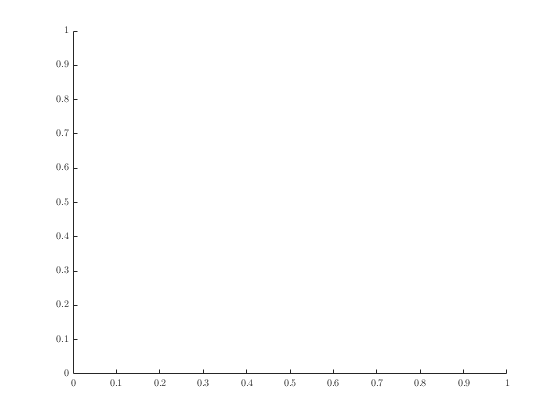

nCycles = 10;

coco = cocoWrapper(DS, nCycles, outdof);
set(coco,'initialGuess','forward')
set(coco,'branchSwitch','true','periodsRatio',2) % include new branches, 2T periodic response
set(coco.Options, 'NAdapt', 1);
set(coco.Options,'ItMX',15,'NTST', 30,'PtMX',60,'bi_direct',false); %for convergence, smaller stepsize

figure(figFRC)
hold on

startcoco = tic;
Sweep_coco = coco.coco_poSweeps(epSamp,OmegaRange);


 Run='FRC0.2': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.59e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1
    0  00:00:06   1.5920e+01      1  EP      1.1201e+01   1.1219e+00   2.0000e-01   0.0000e+00
   10  00:01:00   2.0018e+01      2          1.4126e+01   8.8957e-01   2.0000e-01   0.0000e+00
   20  00:01:42   2.4992e+01      3          1.7657e+01   7.1168e-01   2.0000e-01   0.0000e+00
   22  00:01:47   2.5759e+01      4  EP      1.8201e+01   6.9043e-01   2.0000e-01   0.0000e+00

 Run='FRC0.3': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          0.00e+00  1.59e+01    

timings.cocoFRC = toc(startcoco);

## Stability Diagram from Reduced Dynamics

We extract the stability diagram using continuation of bifurcations. By extending the dynamical system


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{G}(\mathbf{z},\phi)$$


 to an autonomous system of variables $(\mathbf{z}, \tau) \in \mathbb{R}^N \times S^1$ the trivial fixed point $\mathbf{z} =\mathbf{0}$ of the paremtrically excited system can be interpreted as the periodic orbit $(\mathbf{z}, \tau ) = (\mathbf{0}, t \ \text{mod} \ 2\pi )$ . Any change of the stability behaviour of this periodic orbit is then given by some bifurcation. At the stability boundary of the principal resonance with $\Omega \approx 2 \omega_0$ nontrivial periodic orbits with response period $T = 4 \pi / \Omega$ emerge. If continuation of $2 \pi / \Omega$ periodic orbits is used then these bifurcations show up as period doubling ('PD') bifurcations. Initially continuing $4 \pi / \Omega$ periodic orbits leads to a saddle node ('SN') bifurcation. The function extract_Stability_Diagram allows to chose between these two options for constructing the stability diagram.

set(S.contOptions,'PtMX',50,'bi_direct',true)
set(S.FRCOptions,'branchSwitch',true)
PlotSD = true;

p0 = [2*omega0,0]; % Initial condition
epRange = [0,1];

figure();
startSDSSM = tic;
SD = S.extract_Stability_Diagram(resModes, order, OmegaRange,epRange,'amp', p0,'PD',PlotSD);
timings.SDSSM = toc(startSDSSM);
figSD = gcf;


## Verification: Collocation using [coco](https://sourceforge.net/p/cocotools/wiki/Home/)

Dankowicz, H., & Schilder, F. (2013).  *Recipes for Continuation,* SIAM Philadelphia. [<https://doi.org/10.1137/1.9781611972573](https://doi.org/10.1137/1.9781611972573)>

nCycles = 10;

coco_sd = cocoWrapper(DS, nCycles, []);
set(coco_sd.Options,  'PtMX',70, 'bi_direct',true);
set(coco_sd,'branchSwitch',true)

startcoco = tic;
figure(figSD)
SD_full = coco_sd.extract_Stability_Diagram(OmegaRange,epRange,'amp',p0,'SN',PlotSD);
timings.cocoFRC = toc(startcoco);

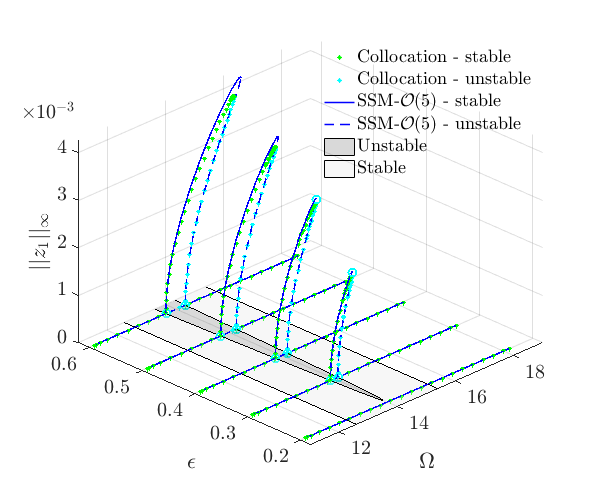

% Plot for Paper
figure()
BBplotSweep(Sweep.FRCom,Sweep_coco,outdof,order);
BBplotSDinSweep(gcf,SD_full);